# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL -  A.Y. 2024/2025

# Full Examination

**June 20, 2025**

# Part 2 - Design of a Controller 

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure

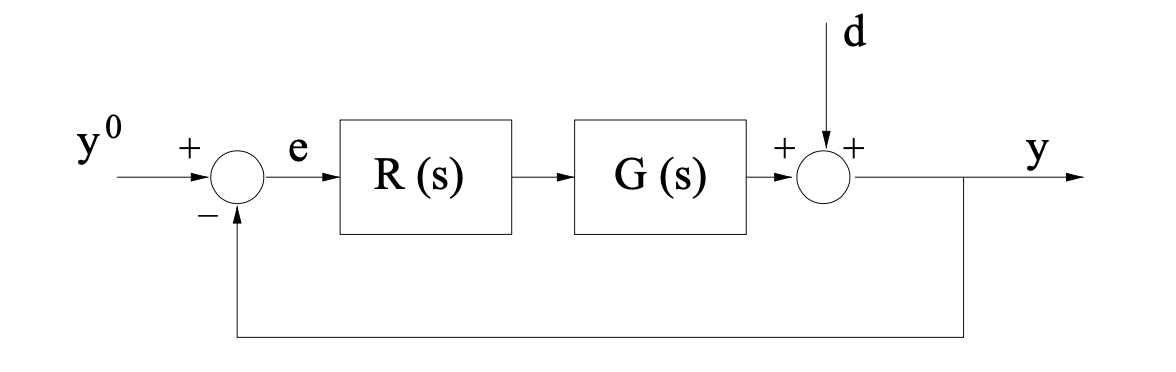	

where $G(s)$ is given by                


$$G(s) = 9\,\frac{\left(1+s \right)}{s\,\left(1+\frac{s}{21} \right)}\,e^{-Ls}\;,\qquad L =\frac{1}{120}\;\text{sec}$$


**Note**: This means that the system has a striclty proper transfer function with two distinct, real poles, only one zero, and a finite delay term.  The delay term's time constant $L$ takes on the value  $L = \frac{1}{120}\;\text{sec.}$

## **Question**		

**Q1**: Design a **proper** **controller** $C(s)$ such that all following requirements are simultaneously met: 

- Zero steady-state error in unit step response (closed-loop) $e(\infty) =0$, against disturbances given by 


$$\left\{ \begin{array}{rcl}
y^o(t) &=& 1(t) \\
d(t) &=& A\cdot 1(t)\,,\; A \in \mathbb{R}
\end{array} \right. \quad \Longrightarrow \quad e_{\infty} = 0
$$


            where $\mathbf{1}(t)$ denotes the unit step function;

- phase margin greater than or equal to $30^\circ$: $\varphi_m \ge 30^{\circ}$;

- settling time [at $1\%$ as usual] in the (closed-loop) unit step output less than or equal to $15$ seconds: $t_{s\,1\%} \le 15$sec.

### Hint

How to handle the delay term? Recall the analysis we performed in Part 9 of the material (**Part 9**, **pp. 49-53**) and the example [DESIGN_1ST_ORDER_DELAY](https://units.sharepoint.com/:f:/r/sites/PATC_CD2024_IN03_034IN_395497/Class%20Materials/MATLAB_LIVE-SCRIPTS/Part_10/CONTROLLER_DESIGN_EXAMPLES_with_SOLUTIONS/DESIGN_1ST_ORDER_DELAY?csf=1&web=1&e=d0V32F), available in the file repository part of the MS Teams course team.

## Foreword to the Provided Solution

The proposed problem admits to more than one possible solution. The proposed solution is not the only admissible solution (in fact, the problem admits to infinite solutions), nor is it optimal. It is only a simple solution that can be obtained using the tools available in MATLAB's Control System Toolbox.

You are encouraged to solve the problem by finding alternative solutions and comparing the performance of the control system using your solution with those obtained using the proposed solution in this live script.  		

## A Solution Proposal

Let's define the transfer function of the process $G(s)$ and configure the MATLAB Search Path, by adding the folder containing the M-code able to compute and plot the asymptotic approximation of the Bode diagrams of the frequency response of a given transfer function.

clear % clear the MATLAB workspace

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

Gtilde = 9*(1+s)/s/(1+s/21); % the process TF WITHOUT THE DELAY TERM
Gs = Gtilde*exp(-s/120) % the complete process TF 


Gs =
 
                    189 s + 189
  exp(-0.00833*s) * -----------
                    s^2 + 21 s
 
Continuous-time transfer function.
Model Properties


### A1: Answer to Question Q1

#### The Static Design	

The design of the controller $C(s)$ is carried out by the following logical steps:

- First, we notice that the delay term $e^{-Ls}$ does not influence the static design, provided that the closed-loop system is asymptotically stable. The designed controller has to ensure the asymptotic stability for the closed-loop system.

- To meet the requirement (Q1.1), the open-loop transfer function $L(s)$ has to be of type $g \ge 1$. Indeed, the transfer function $L(s)$ is already a type $g=1$ transfer function: there is a pole at   $s=0$ with unitary algebraic multiplicity. Thus, the requirement Q1.1 is fulfilled. 

#### The Dynamic Design


$$G(s) = 9\,\frac{\left(1+s \right)}{s\,\left(1+\frac{s}{21} \right)}\,e^{-Ls}\;,\qquad L =\frac{1}{120}\;\text{sec}$$


Consider a generic angular frequency $\bar \omega$. Compute the magnitude and the phase of the frequency response $G(j \bar \omega)$. Note that the magnitude and phase of $G(j \bar \omega)$ as equivalent to the magnitude and phase of the frequency response of a different transfer function $\tilde{G}(s)$, obtained by neglecting the delay term $e^{-Ls}$


$$\begin{array}{l}
\left\vert G(j\,\bar \omega) \right\vert = 9\, \left\vert \frac{1+j\,\bar \omega}{j\,\bar \omega\,\left(1+\displaystyle \frac{j\,\bar \omega}{21} \right)} \right\vert \cdot \left\vert e^{-\frac{j\bar{\omega}}{120}} \right\vert= 9\, \displaystyle \left\vert \frac{1}{\bar \omega} \right\vert \,\left\vert \frac{1+j\,\bar \omega}{1+\displaystyle \frac{j\,\bar \omega}{21} } \right\vert = 
\left\vert \tilde{G}(j\,\omega) \right\vert\\
\arg G(j \bar{\omega}) = \arg \left[\frac{9\,\left(1+j\,\bar \omega \right)}{1+10j \bar \omega} \right]+ \arg e^{-j \frac{\bar{\omega}}{120}} = \arg \tilde{G}(j \bar \omega) + \arg e^{-j \frac{\bar{\omega}}{120}} 
\end{array}$$
		

**Important** **Remark**: we could continue and finish the design of the controller using $\tilde{G}(s)$ instead of $G(s)$, but we need to adjust Req.s (Q1.2) and (Q1.3), taking into account the modifications of the open-loop transfer function due to the introduction of $\tilde{G}(s)$.


$$G(s) = 9\,\frac{\left(1+s \right)}{s\,\left(1+\frac{s}{21} \right)}\,e^{-\, \frac{s}{120}}\quad \Longrightarrow \quad \tilde{G}(s) = 9\,\frac{\left(1+s \right)}{s\,\left(1+\frac{s}{21} \right)}$$
	 

Similarly, let's define $\tilde{L}(s)$ as the open-loop transfer function corresponding to $\tilde{G}(s)$, whereas $L(s)$ corresponds, as usual, to the open-loop transfer function involving the effective plant transfer function $G(s)$.

**Req. (Q1.2)**: We must modify this requirement, to take into account that in $\tilde{G}(s)$ the presence of the delay term $e^{-\, \frac{s}{120}}$ has been neglected. Thus, instead of imposing $\varphi_m \ge 30^{\degree$, we impose 


$$\varphi_m \big(\tilde L(s) \big) \ge 30^{\degree} +  \left\vert \arg e^{-j \frac{\omega_c}{120}} \right\vert \qquad \text{(Q1.2.1)}$$


**Req. (Q1.3)**: We must modify this requirement, to take into account that in $\tilde{G}(s)$ the presence of the delay term $e^{- \,\frac{s}{120}}$ has been neglected. Thus, we impose 


$$t_{s\,1\%} \le 15 \;\text{sec} \quad \Longleftrightarrow \quad
\left\{ \begin{array}{rclcrclcrclcl}
\varphi_m \left(\tilde L\right) \ge 75^{\degree} +  \left\vert \arg e^{-j \frac{\omega_c}{120}} \right\vert &\Longrightarrow& t_{s\,1\%} &\approx&\frac{4.6}{\omega_c} \le 15 &\Longrightarrow& \omega_c \ge \frac{15}{4.6} \approx 3.26 & \qquad & \text{(Q1.3.1a)}\\ \\ 
30^{\degree} +  \left\vert \arg e^{-j \frac{\omega_c}{120}} \right\vert  \le \varphi_m \left(\tilde L\right) <  75^{\degree} +  \left\vert \arg e^{-j \frac{\omega_c}{120}} \right\vert &\Longrightarrow&
 t_{s\,1\%} &\approx&\frac{4.6}{\displaystyle \frac{\varphi_m \left(\tilde L\right)}{100} \, \omega_c} \le 15 &\Longrightarrow& \varphi_m \left(\tilde L\right)\cdot \omega_c > 30.67 & \qquad & \text{(Q1.3.1b)}
\end{array} \right. $$


**First Attempt**: $C(s) = C_1(s) \cdot C_2(s)\,,\quad C_1(s) = \mu_C\;, \quad C_2(s) = 1 \qquad \mu_C =1$

Is the controller $C(s)$ suitable for fulfilling the modified requirements (Q1.2.1) and (Q1.3.1)?

The magnitude and phase Bode diagrams, corresponding to this first design experiment with $\mu_C = 1$, are generated by the following code section. In the figures, the magnitude and the phase of the frequency response, respectively neglecting and applying the delay term, are pointed out using different colors.

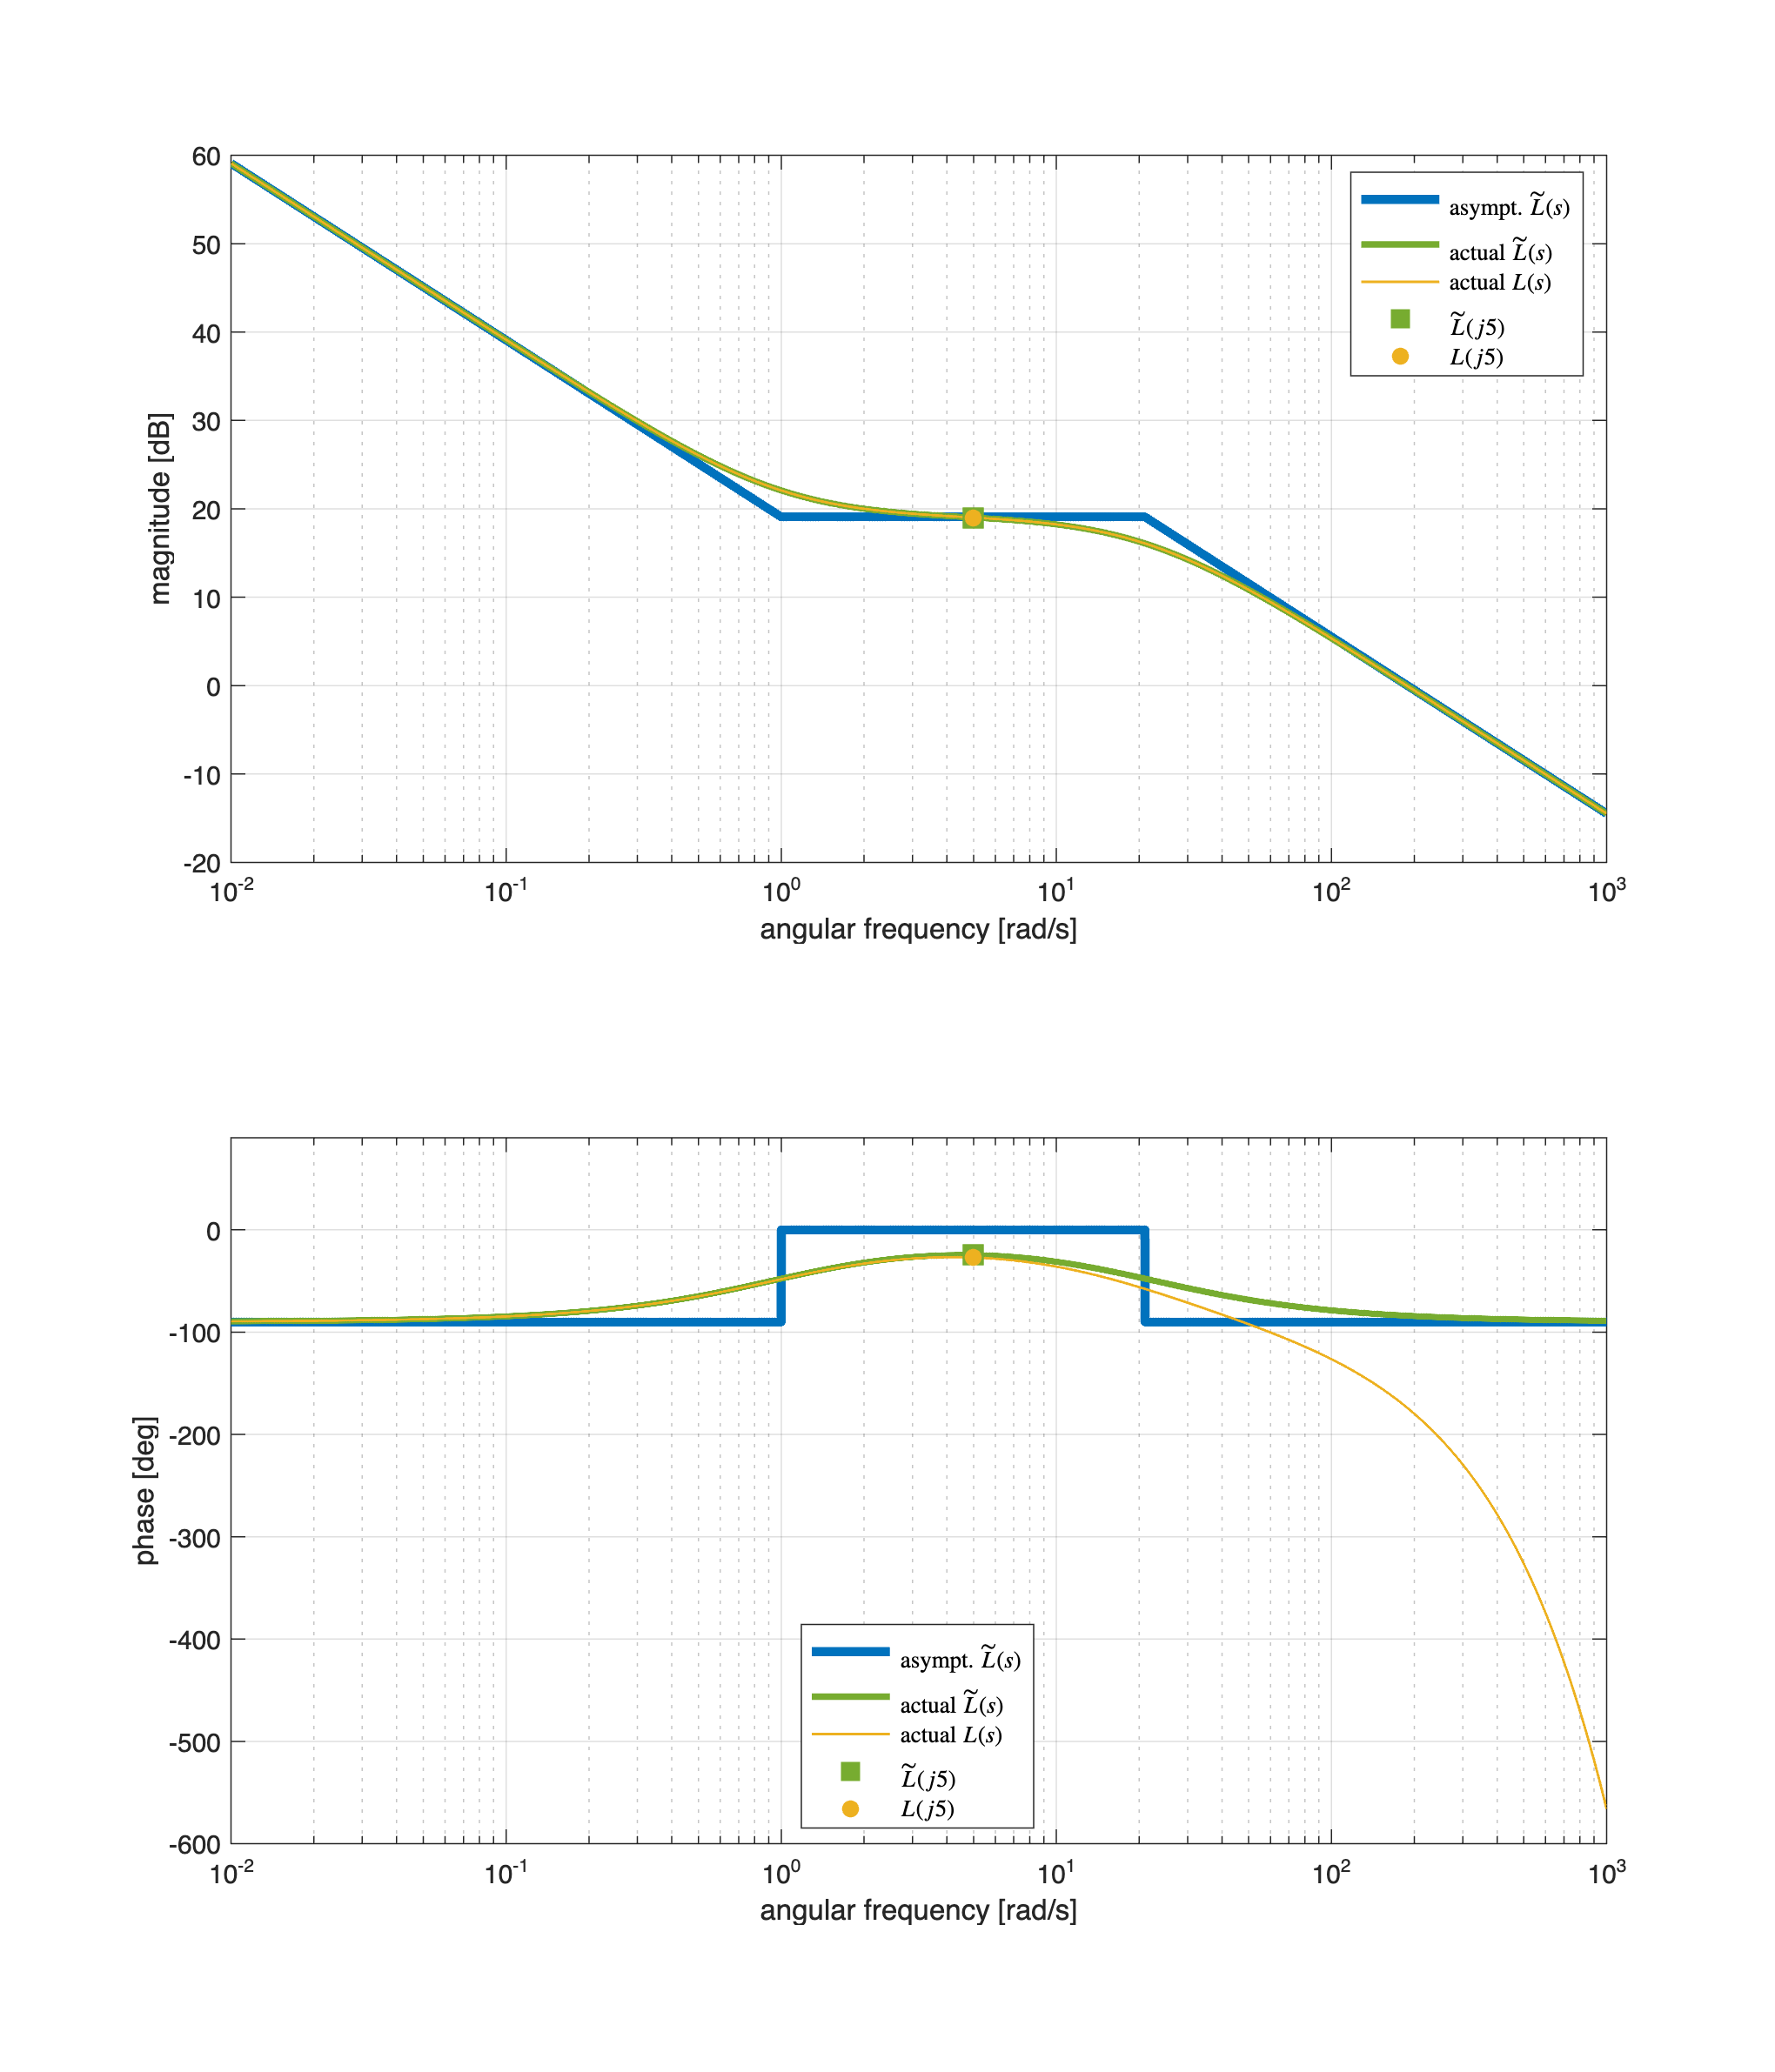

% s=tf('s');
% 
% Gtilde = 9*(1+s)/s/(1+s/21); % the process TF WITHOUT THE DELAY TERM
% Gs = Gtilde*exp(-s/120) % the complete process TF 

muC = 1;
C1s = tf(muC);
C2s = tf(1);
Cs = C1s*C2s;

Ltilde_s = Cs * Gtilde;
Ls = Cs * Gs;

omVALS = logspace(-2,3, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

% straight-line approximation and actuual Bode diagrams of Ltilde(s)
[hax1, hax2] = drawBodediagrams(Ltilde_s, omVALS, Bcolors(1, :), 3.5, '-', ...
                       Bcolors(4, :), 2.5, '-', hf);

% actual Bode diagrams of L(s)
[L_Mag, L_Phase] = bode(Ls, omVALS);
L_Mag_dB = 20*log10(L_Mag(:));
plot(hax1, omVALS, L_Mag_dB, 'Color', Bcolors(2, :),...
     'LineWidth', 1.0, 'LineStyle', '-');
plot(hax2, omVALS, L_Phase(:), 'Color', Bcolors(2, :),...
     'LineWidth', 1.0, 'LineStyle', '-');
ylim(hax2,[-600,  +90]);

% let's eval the frequency response of Ltilde(s) and L(s) at the angular
% frequency bar_omega = 5
barOMEGA = 5.0;
FrResp05 = freqresp(Ls, barOMEGA); % freq. resp. L(s)
L05Mag = 20*log10(abs(FrResp05));
L05Phase = rad2deg(angle(FrResp05)); % 

FrRespTilde05 = freqresp(Ltilde_s, barOMEGA); % freq. resp. Ltilde(s)
LTilde05Mag = 20*log10(abs(FrRespTilde05));
LTilde05Phase = rad2deg(angle(FrRespTilde05)); 

% magnitude & phase for Ltilde(j5) and L(j5)
plot(hax1, barOMEGA, LTilde05Mag, 'Marker','square','MarkerSize',10, ...
      'MarkerEdgeColor',Bcolors(4, :), ...
      'MarkerFaceColor', Bcolors(4, :), ...
      'LineStyle','none');

plot(hax1, barOMEGA, L05Mag, 'Marker','o','MarkerSize',6, ...
      'MarkerEdgeColor',Bcolors(2, :), ...
      'MarkerFaceColor', Bcolors(2, :), ...
      'LineStyle','none');

plot(hax2, barOMEGA, LTilde05Phase, 'Marker','square','MarkerSize',10, ...
      'MarkerEdgeColor',Bcolors(4, :), ...
      'MarkerFaceColor', Bcolors(4, :), ...
      'LineStyle','none');

plot(hax2, barOMEGA, L05Phase, 'Marker','o','MarkerSize',6, ...
      'MarkerEdgeColor',Bcolors(2, :), ...
      'MarkerFaceColor', Bcolors(2, :), ...
      'LineStyle','none');


legend(hax1, 'asympt. $\tilde{L}(s)$', 'actual $\tilde{L}(s)$', ...
             'actual $L(s)$', '$\tilde{L}(j 5)$', '$L(j 5)$',...
             'Interpreter', 'latex', ...
             'Location', 'best');

legend(hax2,  'asympt. $\tilde{L}(s)$', 'actual $\tilde{L}(s)$', ...
             'actual $L(s)$', '$\tilde{L}(j 5)$', '$L(j 5)$',...
             'Interpreter', 'latex', ...
             'Location', 'best');                             

**Note**: 

- the phase responses of $\tilde L(s)$ and $L(s)$ are very close each other when considering the angular frequency interval $\omega \le 10$ rad/sec

- the phase margin is above $75^{\circ}$ when $\omega \le 10$ rad/sec.

Let's insert in the Bode diagrams the graphical constraints corresponding to the requirements (Q1.2.1) and (Q1.3.1)


$$\left\{ \begin{array}{rcl}
 \text{(Q1.2.1)} & \Longrightarrow & \varphi_m \left( \tilde L(j \omega_c) \right) \ge 30^{\degree} +  \left\vert \arg e^{-j \frac{\omega_c}{120}} \right\vert \\
\text{(Q1.3.1a)} & \Longrightarrow & \varphi_m \left(\tilde L(j \omega_c) \right) \ge 75^{\degree} +  \left\vert \arg e^{-j \frac{\omega_c}{120}} \right\vert 
\end{array} \right. \quad \Longrightarrow \quad $$



$$t_{s\,1\%} \le 15 \;\text{sec} \quad \Longleftrightarrow \quad
\left\{ \begin{array}{rclcrclcrcl}
\varphi_m \left(\tilde L\right) \ge 75^{\degree} +  \left\vert \arg e^{-j \frac{\omega_c}{120}} \right\vert &\Longrightarrow& t_{s\,1\%} &\approx&\frac{4.6}{\omega_c} \le 15 &\Longrightarrow& \omega_c \ge \frac{15}{4.6} \approx 3.26 \\ \\ 
30^{\degree} +  \left\vert \arg e^{-j \frac{\omega_c}{120}} \right\vert  \le \varphi_m \left(\tilde L\right) <  75^{\degree} +  \left\vert \arg e^{-j \frac{\omega_c}{120}} \right\vert &\Longrightarrow&
 t_{s\,1\%} &\approx&\frac{4.6}{\displaystyle \frac{\varphi_m \left(\tilde L\right)}{100} \, \omega_c} \le 15 &\Longrightarrow& \varphi_m \left(\tilde L\right)\cdot \omega_c > 30.67
\end{array} \right. \qquad \text{(Q1.3.1)}$$


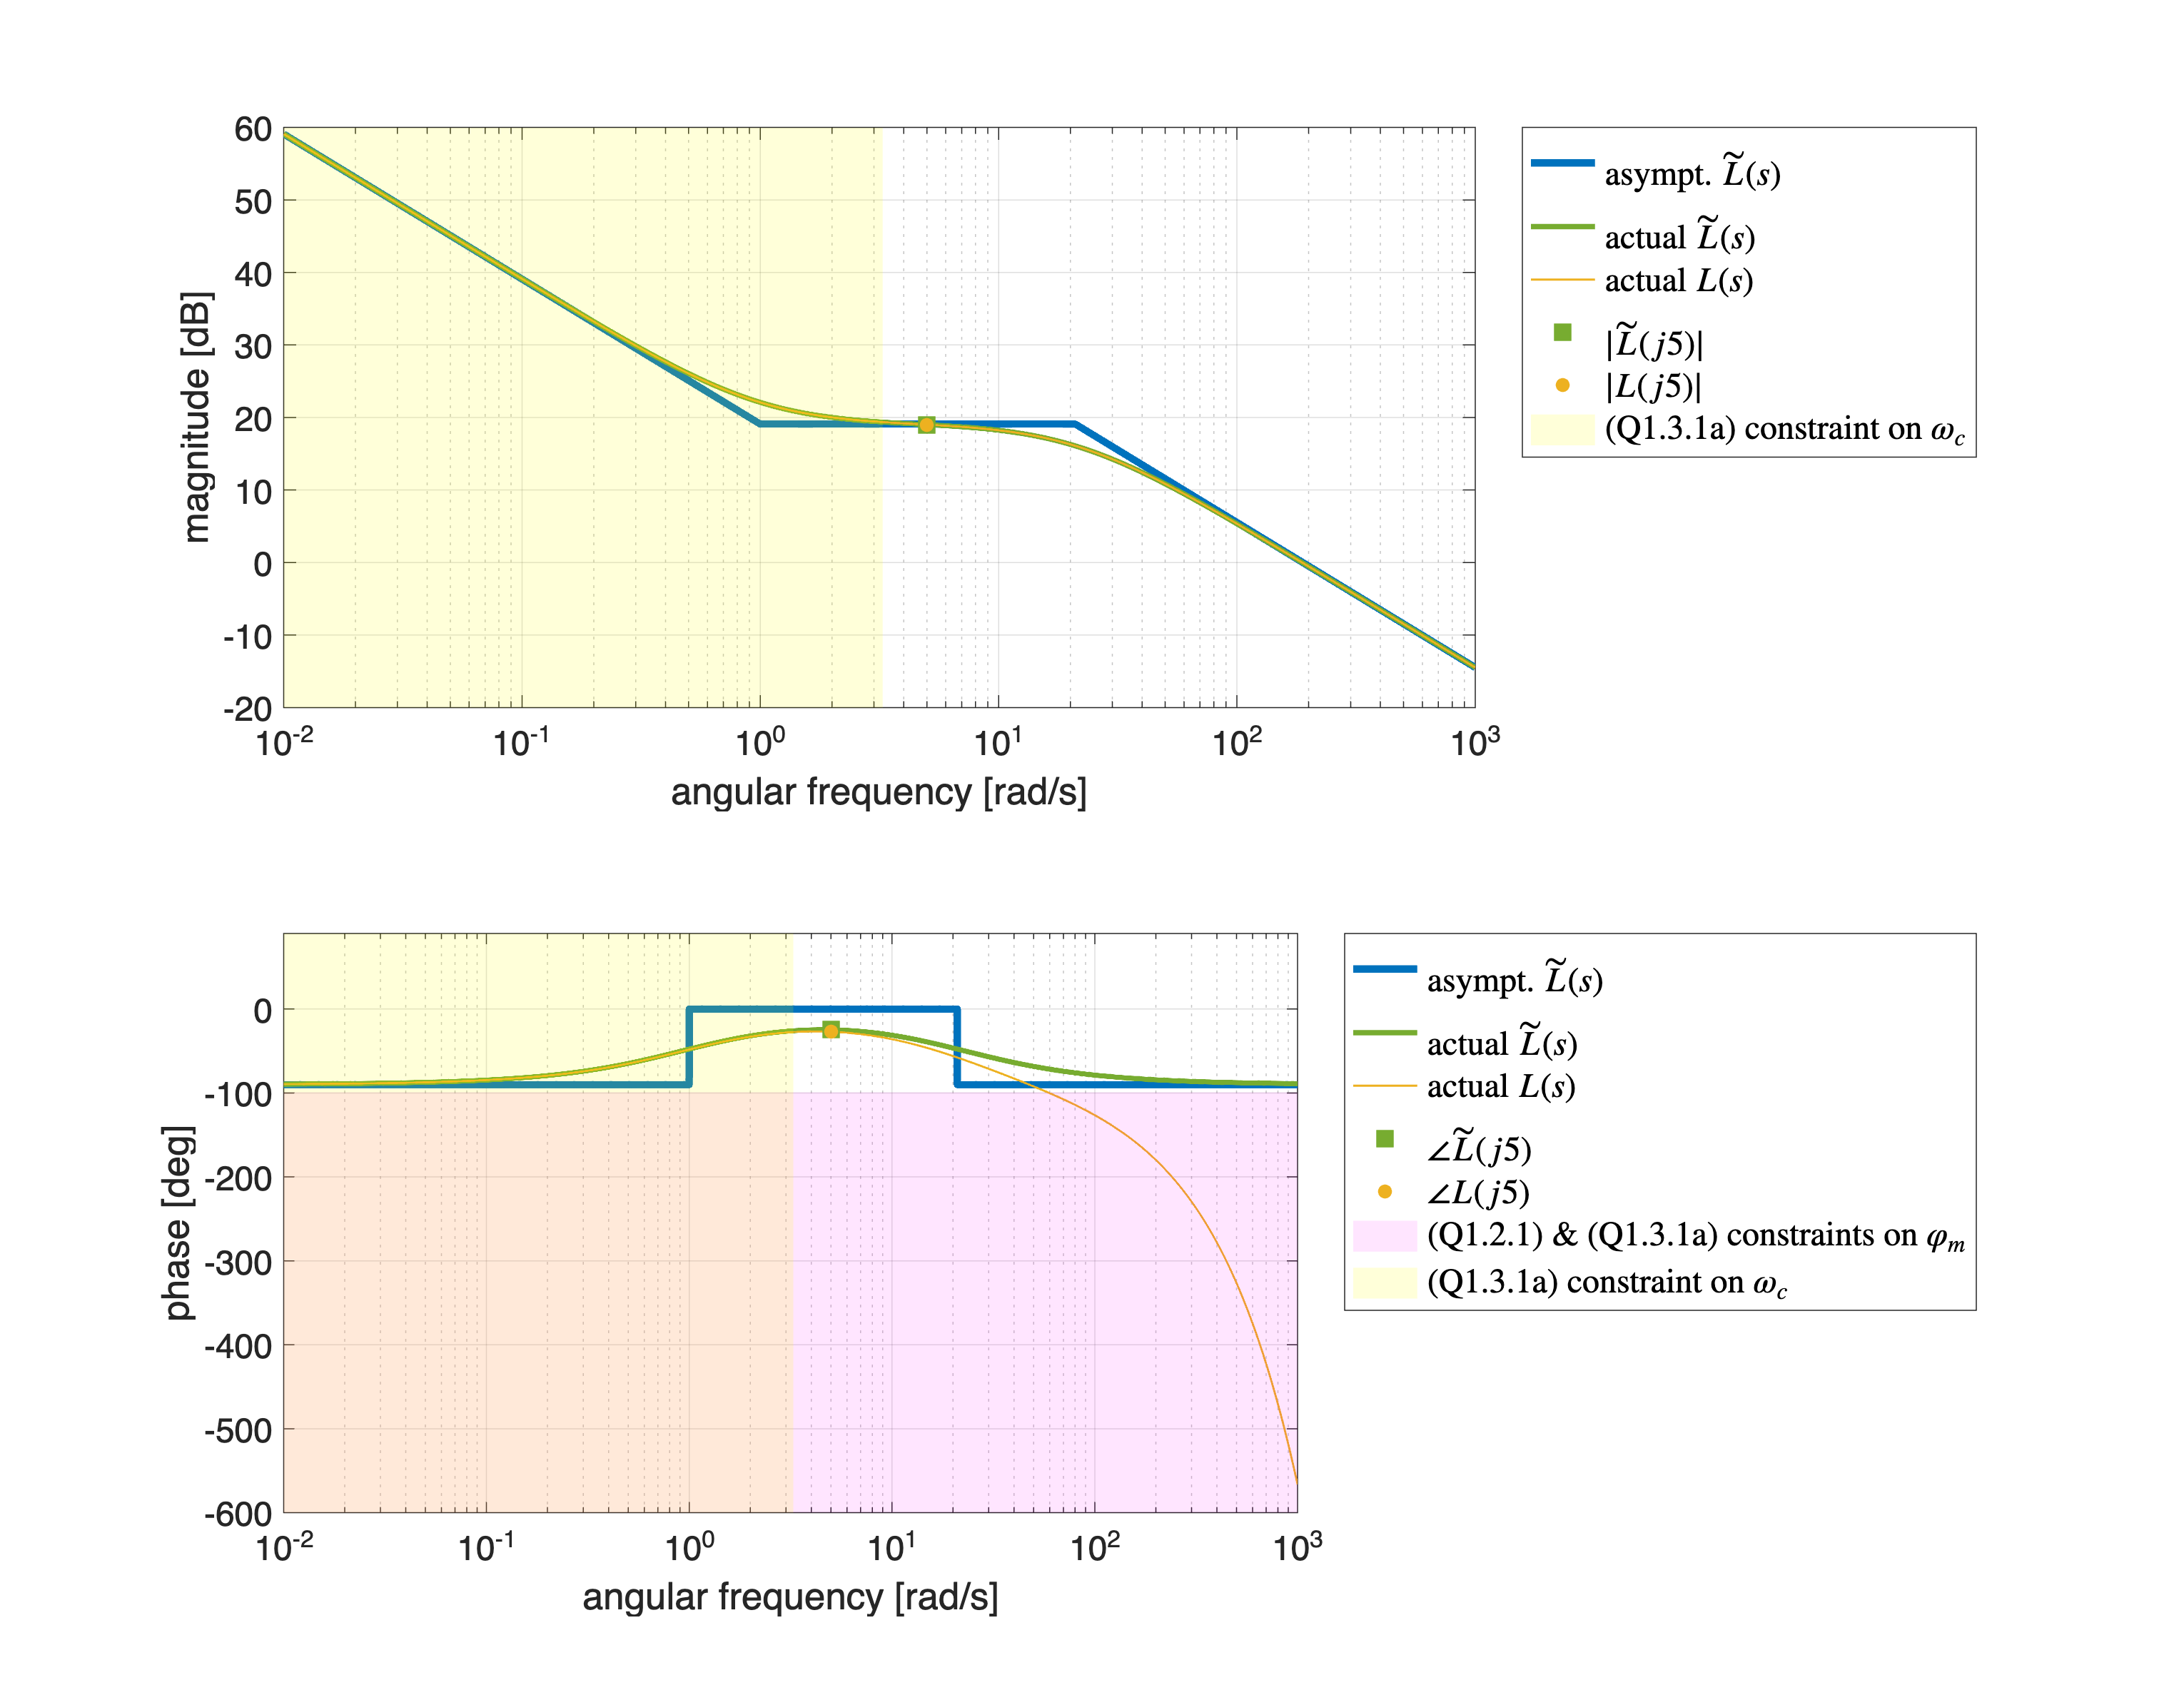

hf = figure('Units','centimeters','Position',[0.01, 0.01, 36, 28]);

% straight-line approximation and actuual Bode diagrams of Ltilde(s)
[hax1, hax2] = drawBodediagrams(Ltilde_s, omVALS, Bcolors(1, :), 3.5, '-', ...
                       Bcolors(4, :), 2.5, '-', hf);

% actual Bode diagrams of L(s)
[L_Mag, L_Phase] = bode(Ls, omVALS);
L_Mag_dB = 20*log10(L_Mag(:));
plot(hax1, omVALS, L_Mag_dB, 'Color', Bcolors(2, :),...
     'LineWidth', 1.0, 'LineStyle', '-');
plot(hax2, omVALS, L_Phase(:), 'Color', Bcolors(2, :),...
     'LineWidth', 1.0, 'LineStyle', '-');
ylim(hax2,[-600,  +90]);

% let's eval the frequency response of Ltilde(s) and L(s) at the angular
% frequency bar_omega = 5
barOMEGA = 5.0;
FrResp05 = freqresp(Ls, barOMEGA); % freq. resp. L(s)
L05Mag = 20*log10(abs(FrResp05));
L05Phase = rad2deg(angle(FrResp05)); % 

FrRespTilde05 = freqresp(Ltilde_s, barOMEGA); % freq. resp. Ltilde(s)
LTilde05Mag = 20*log10(abs(FrRespTilde05));
LTilde05Phase = rad2deg(angle(FrRespTilde05)); 

% magnitude & phase for Ltilde(j5) and L(j5)
plot(hax1, barOMEGA, LTilde05Mag, 'Marker','square','MarkerSize',10, ...
      'MarkerEdgeColor',Bcolors(4, :), ...
      'MarkerFaceColor', Bcolors(4, :), ...
      'LineStyle','none');

plot(hax1, barOMEGA, L05Mag, 'Marker','o','MarkerSize',6, ...
      'MarkerEdgeColor',Bcolors(2, :), ...
      'MarkerFaceColor', Bcolors(2, :), ...
      'LineStyle','none');

plot(hax2, barOMEGA, LTilde05Phase, 'Marker','square','MarkerSize',10, ...
      'MarkerEdgeColor',Bcolors(4, :), ...
      'MarkerFaceColor', Bcolors(4, :), ...
      'LineStyle','none');

plot(hax2, barOMEGA, L05Phase, 'Marker','o','MarkerSize',6, ...
      'MarkerEdgeColor',Bcolors(2, :), ...
      'MarkerFaceColor', Bcolors(2, :), ...
      'LineStyle','none');

set(hax1, 'FontSize', 16);
set(hax2, 'FontSize', 16);

% ---- Let's consider the requirements (Q1.3.1a) & (Q1.2.1) ----

reqPM = 75+abs(rad2deg(-12/120) );     % the phase margin according to Q1.3.1a
                                       % evaluated considering as "final"
                                       % scenario the case when the
                                       % crossover angular frequency is
                                       % \omega_c = 12 rad/sec
feas_Ls_Phase = -180+reqPM; % the minimum value of the arg L(j omega) 
                            % to guarantee the feasibility of the design

reqOM = 15/4.6; % the minimum value for the crossover angular frequency according to Q1.3.1a

% ------- the phase constraint ----
YLIMS = ylim(hax2);
OMLIMs = xlim(hax2);

% the box describing the PM constraint
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
PhLIM = feas_Ls_Phase;

Vert1 = [minOmega1 ,  YLIMS(1); minOmega1 ,PhLIM; ...
         maxOmega1 , PhLIM; maxOmega1 , YLIMS(1)];
Faces1 = [1  2  3  4];
%hold on;
patch(hax2, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','magenta','FaceAlpha',.10, ...
        'EdgeColor', 'none'); % the pale magenta region is the forbidden one
% ------- the phase constraint ----

% ---- the constraint on the crossover angular frequency, due to the
% settling time constraint ----
omCMIN = reqOM; 

YLIMS = ylim(hax1);
OMLIMs = xlim(hax1);
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
Vert2 = [minOmega1 ,  YLIMS(1); omCMIN ,YLIMS(1); ...
         omCMIN , YLIMS(2); minOmega1 , YLIMS(2)];
Faces2 = [1  2  3  4];
hold on;
patch(hax1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

YLIMS = ylim(hax2);
OMLIMs = xlim(hax2);
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
Vert3 = [minOmega1 ,  YLIMS(1); omCMIN ,YLIMS(1); ...
         omCMIN , YLIMS(2); minOmega1 , YLIMS(2)];
Faces3 = [1  2  3  4];
patch(hax2, 'Faces',Faces3,'Vertices',Vert3,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one
% ---- the constraint on the crossover angular frequency, due to the
% settling time constraint ----



legend(hax1, 'asympt. $\tilde{L}(s)$', 'actual $\tilde{L}(s)$', ...
             'actual $L(s)$', '$\vert \tilde{L}(j 5) \vert$', '$\vert L(j 5) \vert$',...
             '(Q1.3.1a) constraint on $\omega_c$',...
             'Interpreter', 'latex', ...
             'FontSize', 16, ...
             'Location', 'bestoutside');

legend(hax2,  'asympt. $\tilde{L}(s)$', 'actual $\tilde{L}(s)$', ...
             'actual $L(s)$', '$\angle \tilde{L}(j 5)$', '$\angle  L(j 5)$',...
             '(Q1.2.1) \& (Q1.3.1a) constraints on $\varphi_m$', ...
             '(Q1.3.1a) constraint on $\omega_c$',...
             'Interpreter', 'latex', ...
             'FontSize', 16, ...
             'Location', 'bestoutside');

**Note**: every **design** **attempt** with $C(s) = \mu_C$ will surely **meet** **all** the **requirements** if you impose a **crossover** **frequency** in the **interval** $\omega_c \in \mathbf{\big[4\,,\; 20\big]}\;\text{rad/sec}$ (in the Figure above, the crossover frequency candidate is $\bar \omega = 5 \; \text{rad/sec}$ ).

**Second Attempt**

According to the analysys performed above, let's apply a simple proportional controller $C(s) = \mu_C\,,\; \mu_C \in \mathbb{R}$and choose the angular frequency $\bar \omega = 5 \; \text{rad/sec}$ as a candidate for the crossover frequency $\omega_c$.

% s=tf('s');
% 
% Gtilde = 9*(1+s)/s/(1+s/21); % the process TF WITHOUT THE DELAY TERM
% Gs = Gtilde*exp(-s/120) % the complete process TF 

% muC = 1;
% C1s = tf(muC);
% C2s = tf(1);
% Cs = C1s*C2s;
% 
% Ltilde_s = Cs * Gtilde;
% Ls = Cs * Gs;

barOmega = 5; % rad/sec NB 4 <= barOmega < 21 rad/sec

tildeLFR = freqresp(Ltilde_s, 1j*barOmega); % frequency response at the ang. frequency barOmega

% let's tune the controller, by imposing barOmega as the effective
% crossover frequency
muC = 1/abs(tildeLFR)

muC = 0.1120

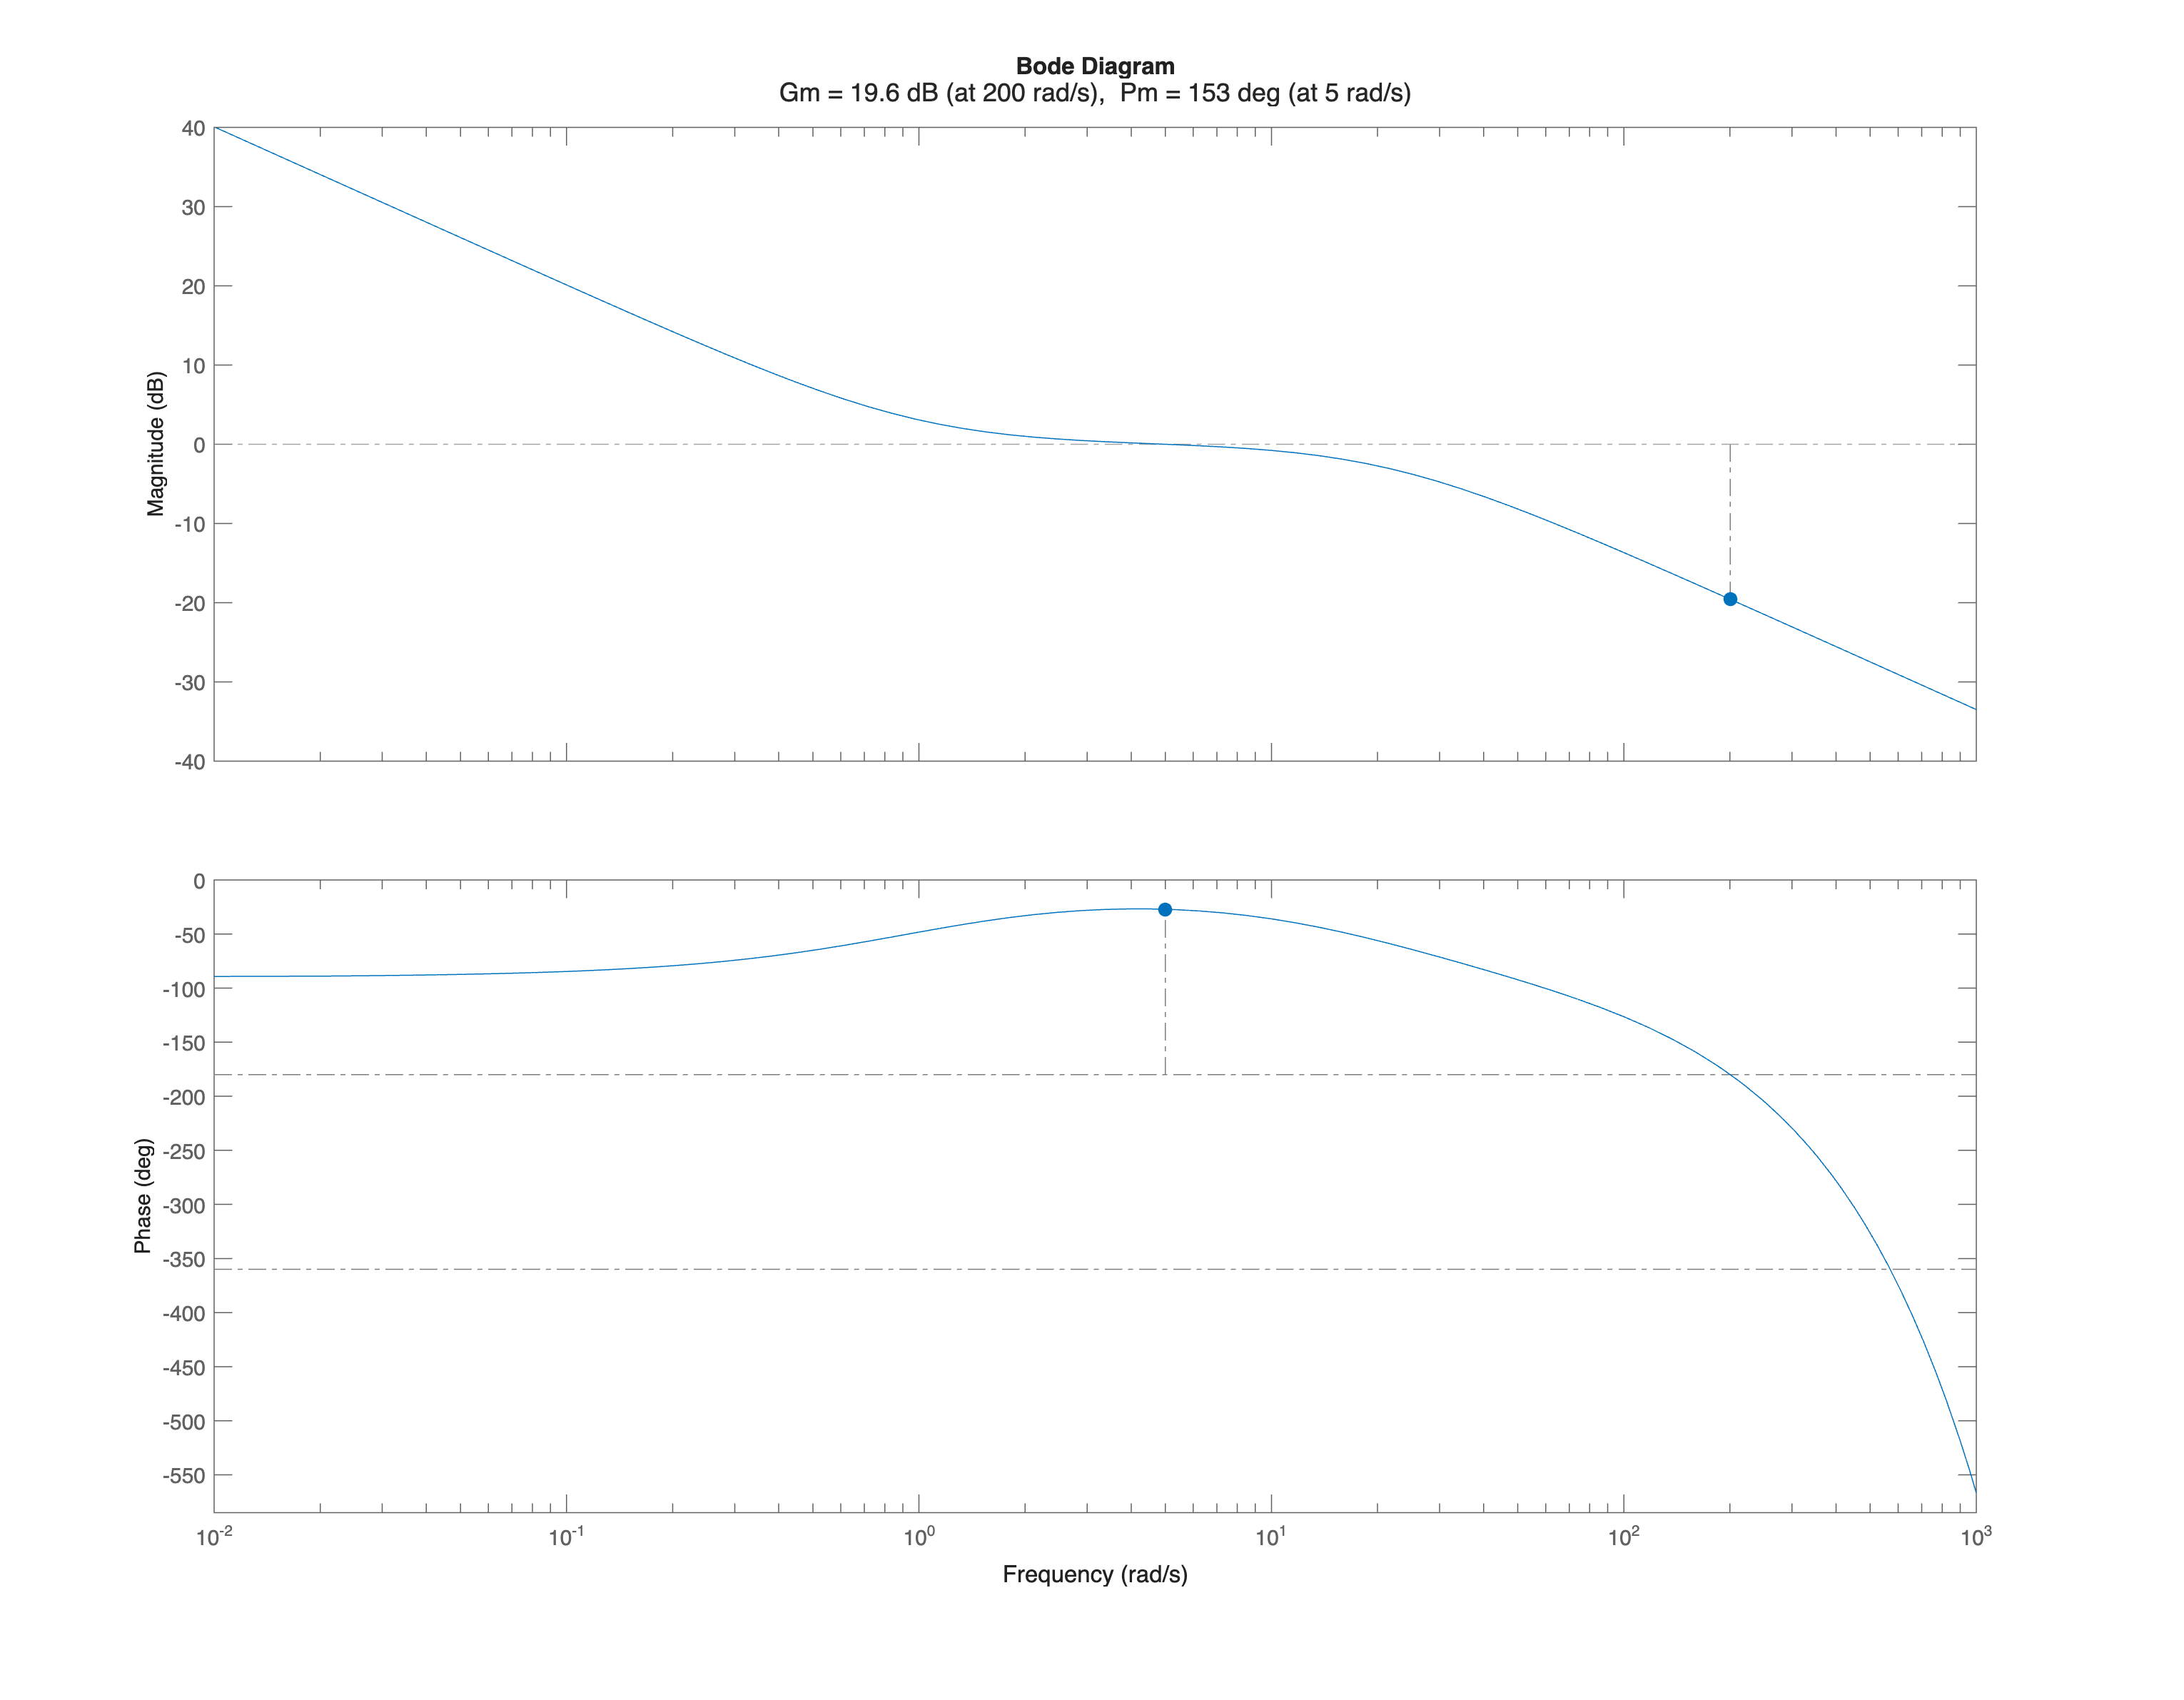


% now let's check the performance of the complete system
% with the delay term

Cs = muC;                   % the final controller
Ltilde_s_FINAL = Cs*Gtilde; % the open-llop transfer function, without the delay term
Ls_FINAL = Cs*Gs;           % the complete open-loop transfer function
FsFINAL = feedback(Ls_FINAL, 1, -1); % the closed-loop LTI syste
% NB for internal efficiency, MATLAB uses a state-space representation here, not a transfer-function based one!

figure('Units','centimeters','Position',[0.01, 0.01, 36, 28]);
margin(Ls_FINAL)

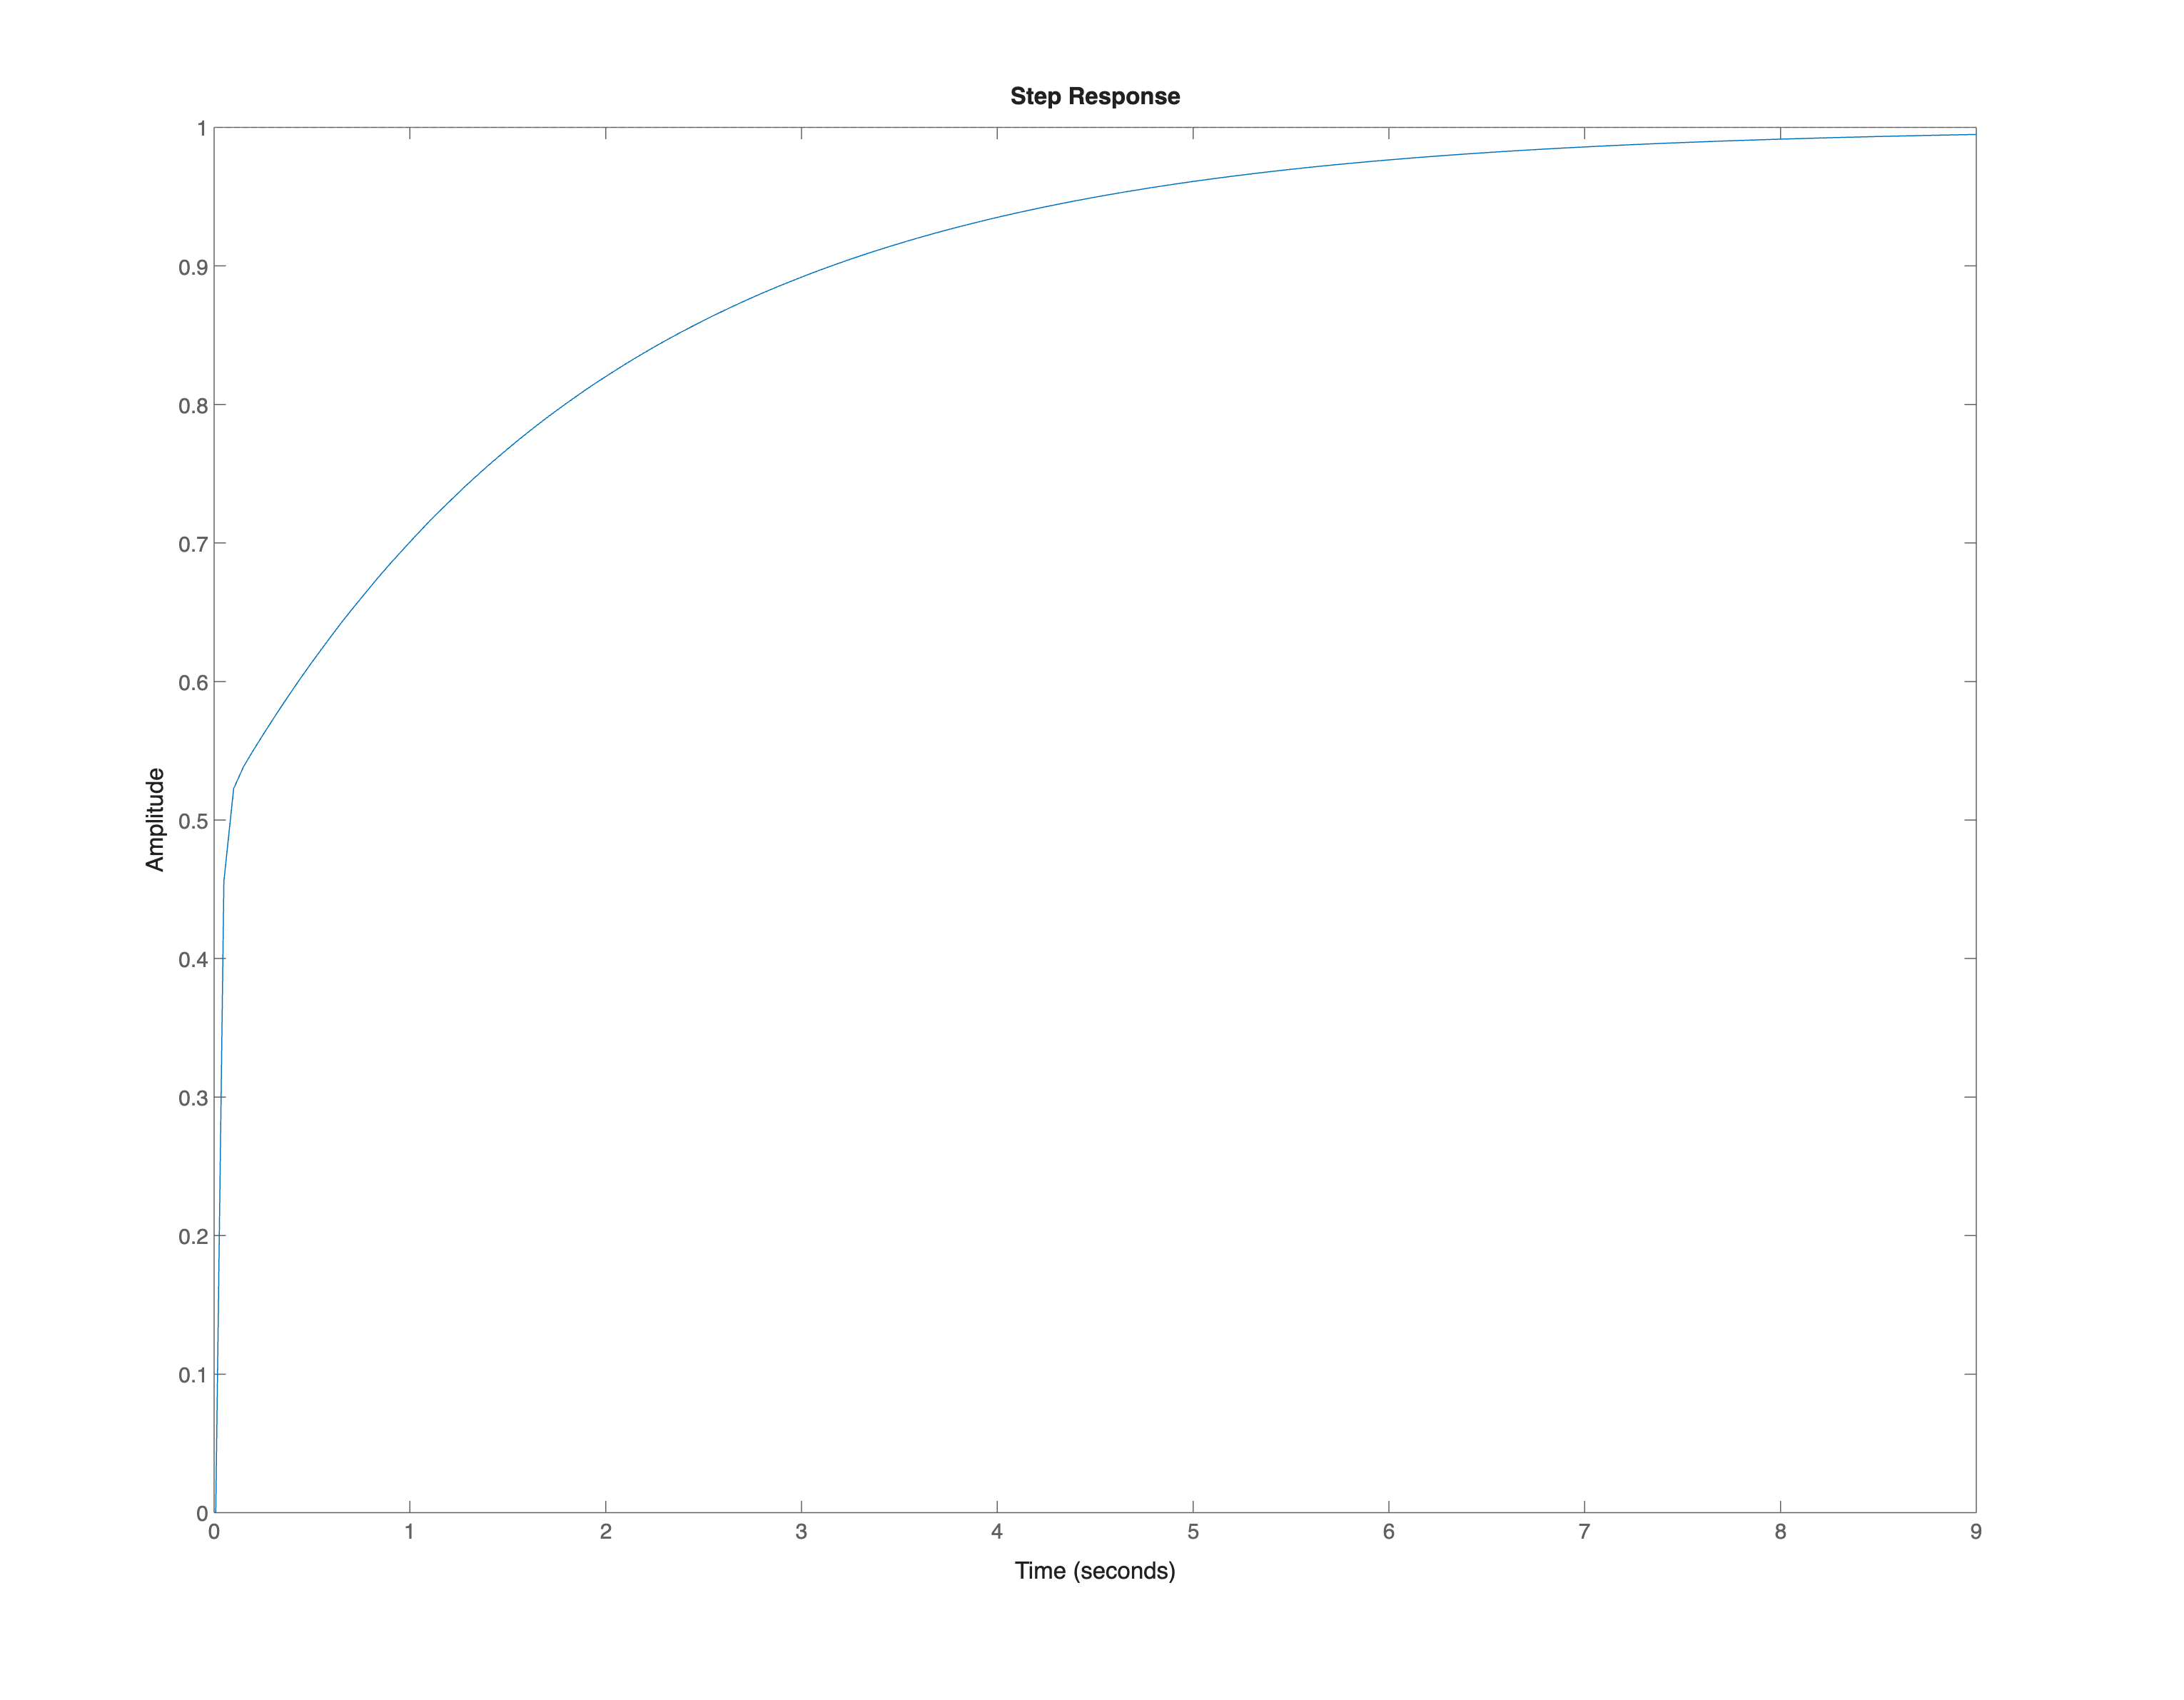



figure('Units','centimeters','Position',[0.01, 0.01, 36, 28]);
step(FsFINAL)

% Refer to the live script example in Part 7 of the course material
FsStepINFO = stepinfo(FsFINAL, "SettlingTimeThreshold", 0.01)

FsStepINFO = struct with fields:
         RiseTime: 3.1352
    TransientTime: 7.6761
     SettlingTime: 7.6761
      SettlingMin: 0.9020
      SettlingMax: 0.9992
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9992
         PeakTime: 12.6346

All the requirements have been met. The final controller is $C(s) = 0.112$.

#### Fine Tuning of the Controller

Let's import the process $G(s)$ and the controller $C(s)$ transfer functions in the ***Control System Design App***, for a fine tuning.

controlSystemDesigner(Gs, Cs)

As you can note, there is no need for any additional tuning.

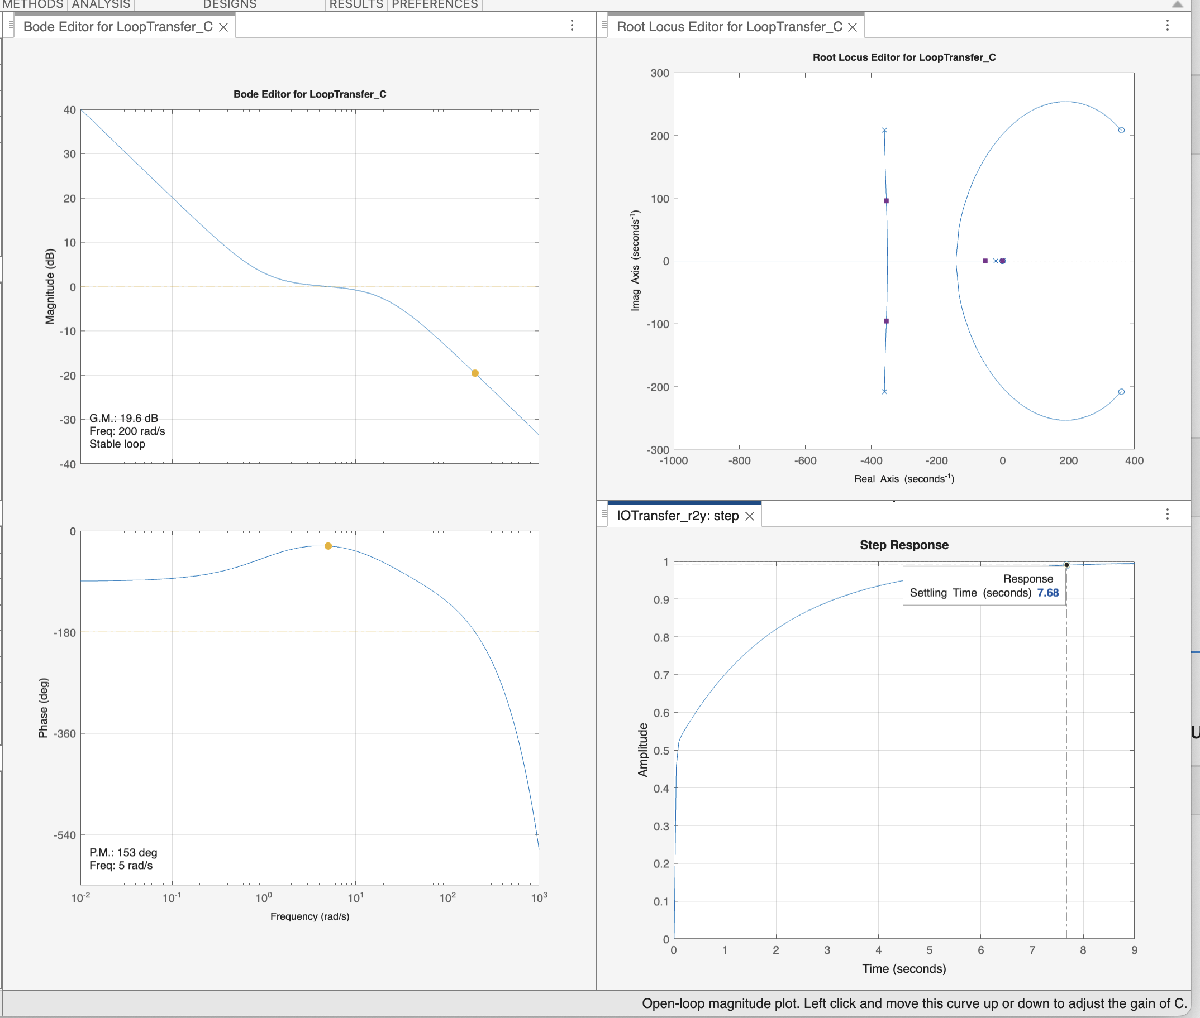

You will find the session data corresponding to the above Figure in the MAT file named `SOLUTION_FA2025_06_20_AY24_25_DESIGN_PROBLEM.MAT`	